为了run模型TP1_EX2

num_G=1;
den_G=[1 0.2683 5];
G=tf(num_G,den_G);
wb=1.5;
b=1.5;
sse=1e-4; % steady-state error
M=2;

den=[1/M wb];
num=[1 wb*sse];

W1=tf(den,num);
W2=0.1;
W3=0;
P = augw(G,W1,W2,W3);
[K,CL,gamma,info] = hinfsyn(P,1,1);
wb=5;
den2=[1/M wb];
num2=[1 wb*sse];
W1_=tf(den2,num2);
W2_=0.1;% 0.01\ 0.1\1
P2 = augw(G,W1_,W2_,W3);
[K2,CL2,gamma2] = hinfsyn(P2,1,1);


[A,B,C,D]=tf2ss(num_G,den_G);
sys = ss(A,B,C,D);
Q = 1*eye(2,2);
R = 1e-7;
QXU = blkdiag(Q,R);
Qn = eye(2);
Rn = 2;
QWV = blkdiag(Qn,Rn);
reg = lqg(sys,QXU,QWV)


reg =
 
  A = 
            x1_e     x2_e
   x1_e    -3163    -3162
   x2_e        1  -0.5555
 
  B = 
               y1
   x1_e  -0.09572
   x2_e    0.5555
 
  C = 
        x1_e   x2_e
   u1  -3163  -3157
 
  D = 
       y1
   u1   0
 
Input groups:              
       Name        Channels
    Measurement       1    
                           
Output groups:          
      Name      Channels
    Controls       1    
                        
Continuous-time state-space model.



p =            -2 +        2.2i
           -2 -        2.2i



z =

  空的 0×1 double 列向量



ErrorMax =     0.0019458


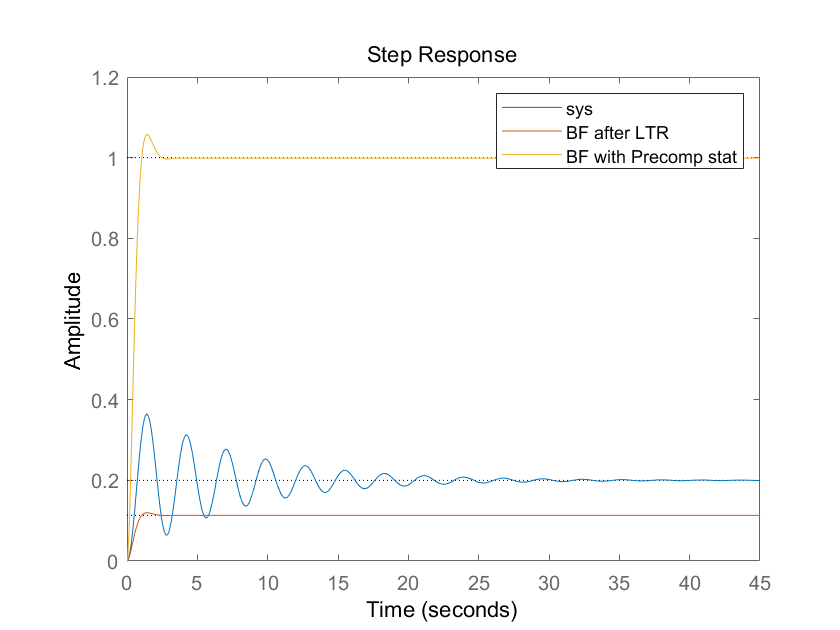

F =        3.7317        3.982


K_ltr =        17.389
       9.7317



BF =
 
         1
  ----------------
  s^2 + 4 s + 8.84
 
Continuous-time transfer function.



precomp_stat =          8.84



[F,K_ltr,BF,precomp_stat] = LTR(sys, 0.5, 0.2)

A_ob = P.A;
B_ob = [P.B, info.Lx];
C_ob = eye(length(P.A));
D_ob = zeros(size(B_ob));

Kw = info.Kw;
Ku = info.Ku;
Lu = info.Lu;
Lx = info.Lx;

C2 = P.C(4,:);
D21 = P.D(4,1);
D22 = P.D(4,2);
